# Ajustement des paramètres de collision

## Fonction de probabilité de collision $p(\Delta z)$

On définir la probabitlité $p$ de collision entre deux particules comme une fonction de la distance $\Delta z$ entre les deux particules. On doit avoir :

- 
$$p(0) = max(p(\Delta z))$$


- 
$$p\left(\|\Delta z\| = \frac{d_1+d_2}{2}\right) = 1$$


- 
$$p\left(\|\Delta z\| \to \delta_{max} + \frac{d_1+d_2}{2}\right) \to 0$$


- 
$$p\left(\|\Delta z\| > \delta_{max} + \frac{d_1+d_2}{2}\right) < 0$$


Il faut donc une fonction paire ($f(-x)=f(x)$) , décroissante sur $[0,\infty]$.

On choisit une fonction $p$ Gaussienne :


$$p(\Delta z) = ae^{-\frac{(\Delta z+b)^2}{2c^2}}+d$$


- $a$ : hauteur du pic, $a>1$

- $b$ : position du pic, $b=0$

- $c$ : équart type, inconnu

- $d$ : translation verticale de la courbe, $d<0$

En fixant $c$ on obtient :


$$\begin{cases} {p\left(\frac{d1+d2}{2}\right)=1}&{}\\ {p\left(\delta_{max}+\frac{d1+d2}{2}\right)=0}&{}\\ \end{cases} \Rightarrow \begin{cases} {a\,=\left(1-d\right)e^{\frac{\left(\frac{d1+d2}{2}\right)^{2}}{2c²}}}&{}\\ {\frac{1}{d}\,=1-e^{\frac{\delta_{max}^{2}+\delta_{max}\left(d1+d2\right)}{2c²}}}&{}\\ \end{cases}$$


On va donc chercher à calibrer $c$ par rapport à des données de collision pour un pas de temps $dt \leq dt_{max}$.

## Obtention des données de collision

$z(t-dt)$ est retenu pour chaque particule à chaque pas de temps. Si une collision a lieu à $t$, on garde en mémoire $\Delta z(t-dt)$, $\delta_{max}$, $d_1$ et $d_2$).

À la fin de la simulation on trace l'histogrames des $\Delta z(t-dt)$ ayant conduit à une collision à $t$ en fonction de $\delta_{max} + \frac{d_1+d_2}{2}$. 

clear,

dt_test = 0.00001;
date = datetime(2020,03,18);
tf = 0.1;

dtTheoB = tf;
% dt_testB = dtTheoB/2;

%% Water column parameters
% Find depth of the column
load('../Data/2020waterCol_RN2.mat', 'H0')
L = H0; % depth
clear H0,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 1e3;
% pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
% sizeMP = random(pd,nMP,1);
% sizeMP(sizeMP<1e-6) = 1e-6;
% clear pd,
sizeMP = ones(nMP,1)*450e-6;
zInitMP = linspace(29.9,30.1,nMP);
% zInitMP = ones(nMP,1)*30.5;
rhoMP = 1000;

nAgg = 1;
% pd = makedist('Normal', 'mu', 2e-2, 'sigma', 1e-2);
% sizeAgg = random(pd,nAgg,1);
% sizeAgg(sizeAgg<1e-6) = 1e-6;
sizeAgg = ones(nAgg,1)*1e-3;
% clear pd,
% zInitAgg = linspace(30,31,nAgg);
zInitAgg = 30;
rhoAgg = 1040;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
K = 0.01*ones(size(K));
dK = zeros(size(dK));
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,



--------------------- Simulation running ---------------------


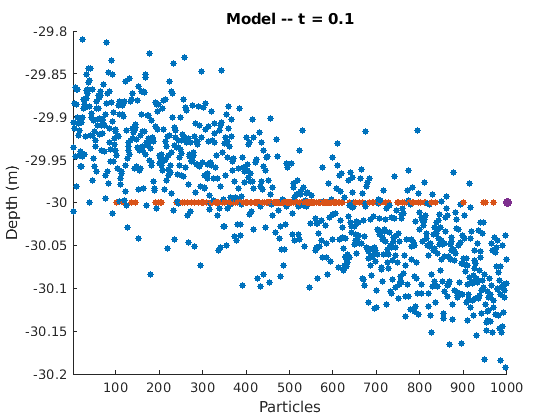

path = '../Results/Aggr/';
nameMat = [ 'm_' num2str(tf) 's_cstK.mat'];

[collisionB, dtB,mpZB,aggZB,mpListB,aggListB] = Part_SimulatorBoom(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTheoB);

save([path 'collisionB_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat], 'collisionB', 'dtB','mpZB','aggZB','mpListB','aggListB')

colTestB = cell2mat(collisionB');   
DataColB = colTestB(:,1);

clear colTestB collisionB aggListB mpListB,



--------------------- Simulation running ---------------------


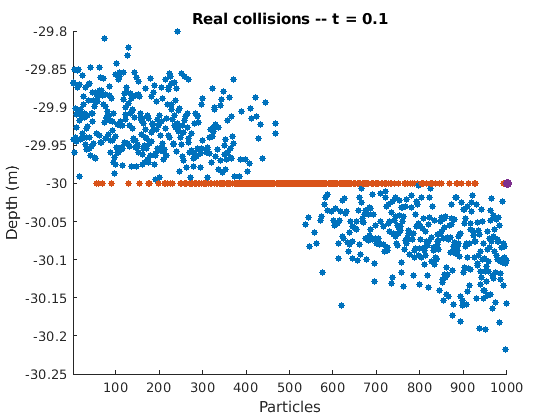

[collisionA, dtA,mpZA,aggZA,mpListA,aggListA] = Collision_Simulator(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtB);

save([path 'collisionA_' num2str(min(zInitMP)) '-' num2str(max(zInitMP)) nameMat], 'collisionA', 'dtA','mpZA','aggZA','mpListA','aggListA')

colTestA = cell2mat(collisionA');
DataColA = colTestA(:,1);

clear colTestA  collisionA  aggListA   mpListA  ,

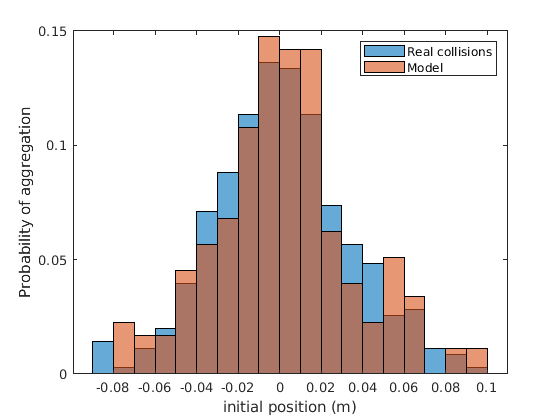

hA = histogram(DataColA,'Normalization','probability','BinWidth', 0.01, 'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'Normalization','probability' ,'BinEdges',hA.BinEdges,'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Probability of aggregation")

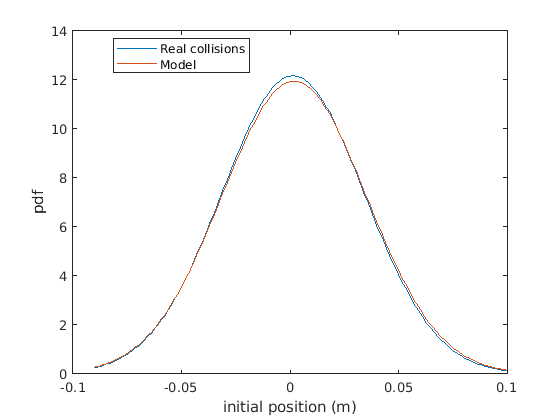


% pd = makedist('Normal',"mu",0,"sigma",std(DataCol));
% pdFit = fitdist(DataCol,'Kernel')
% % gaussienneTest = pdf(pd,h.BinEdges);
% gaussienneFit = pdf(pdFit,h.BinEdges);
% % plot(h.BinEdges,gaussienneTest)
% plot(h.BinEdges,gaussienneFit)
% hold off,
fitA = fitdist(DataColA,'Normal');
fitB = fitdist(DataColB,'Normal');
xfit = hA.BinLimits(1):1e-3:hA.BinLimits(2);


plot(xfit,pdf(fitA,xfit),'DisplayName','Real collisions')
hold on,
plot(xfit,pdf(fitB,xfit),'DisplayName','Model')
hold off,
% xline((mean(sizeAgg)+mean(sizeMP))/2)
legend('Location','best')
xlabel('initial position (m)')
ylabel("pdf")

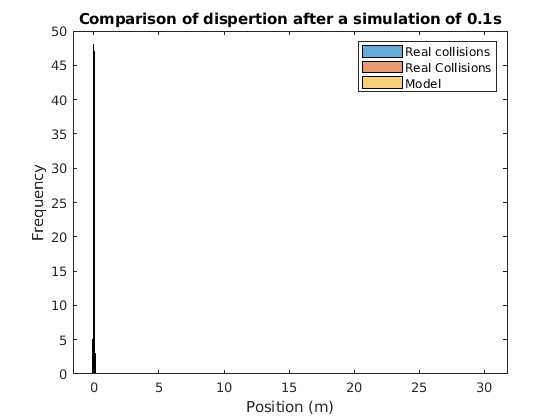

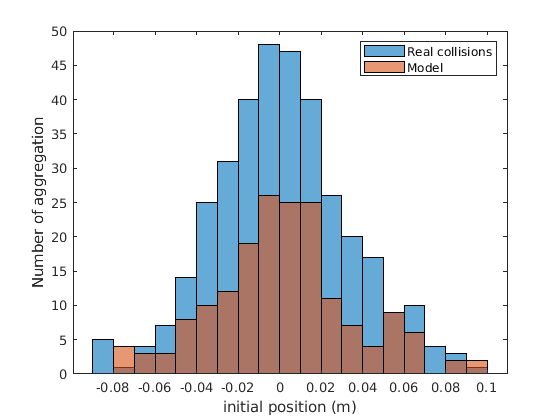

zHA = histogram(mpZA,'Normalization','probability',"DisplayName",'Real Collisions');
hold on,
zHB = histogram(mpZB,'Normalization','probability', 'BinEdges', zHA.BinEdges, "DisplayName",'Model');
hold off
legend
title(['Comparison of dispertion after a simulation of ' num2str(tf) 's'])
xlabel('Position (m)')
ylabel('Frequency')

hA = histogram(DataColA,'BinWidth', 0.01, 'DisplayName','Real collisions');
hold on,
hB = histogram(DataColB,'BinEdges',hA.BinEdges,'DisplayName','Model');
hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

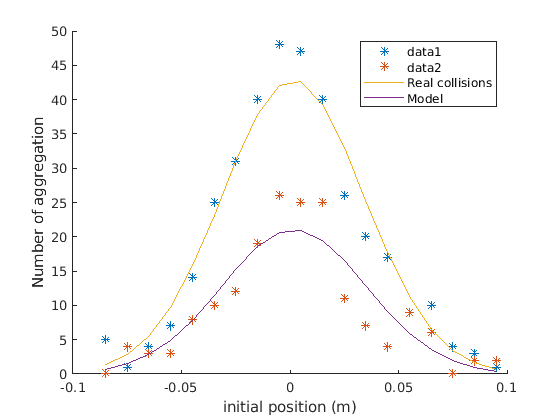

xA = hA.BinEdges(1:end-1)+hA.BinWidth/2;
yA = hA.Values;
xB = hB.BinEdges(1:end-1)+hB.BinWidth/2;
yB = hB.Values;
dxA = hA.BinWidth;
dxB = hB.BinWidth;


clf, hold on,
plot(xA,yA,'*')
plot(xB,yB,'*')

plot(xA,pdf(fitA,xA).*dxA.*numel(DataColA),'DisplayName','Real collisions')
plot(xB,pdf(fitB,xB).*dxB.*numel(DataColB),'DisplayName','Model')

hold off,
legend
xlabel('initial position (m)')
ylabel("Number of aggregation")

Soit $\gamma$ le facteur multiplicatif entre le modèle et les collisions réelles.

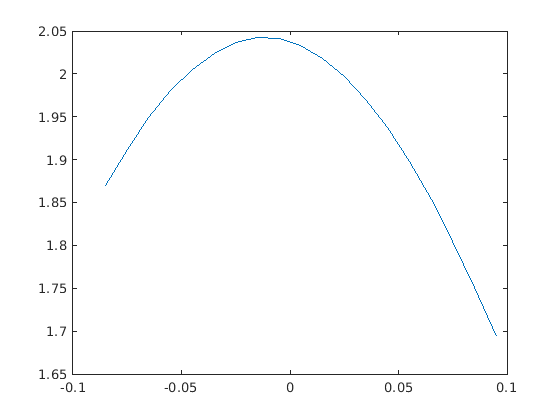

xDiff = -0.2

gamma_dt = pdf(fitA,xA).*dxA.*numel(DataColA)./(pdf(fitB,xB).*dxB.*numel(DataColB));
plot(xA,gamma_dt)

On va chercher comment évolue $\gamma$ pour différentes valeurs de $K$ et $dt$.

## Évolution du facteur $\gamma$ en fonction des paramètres $K$ et $dt$

### En fonction de $dt$

dzInit = 0.01;
initDistBin = -0.1:dzInit:0.1;
initDistBin_ = (initDistBin(1:end-1)+initDistBin(2:end))./2;

gamma_dt = nan(length(dtTheo_test),length(initDistBin_));

Unrecognized function or variable 'dtTheo_test'.

gammaMean_dt = nan(length(dtTheo_test),1);
rmse_dt = nan(length(dtTheo_test),1);
for idt = 1:length(dtTheo_test)
    DataColA = savedCollisions{idt,1};
    DataColB = savedCollisions{idt,2};
    fitA = fitdist(DataColA,'Normal');
    fitB = fitdist(DataColB,'Normal');
    gamma_dt(idt,:) = pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)./(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB));
    gammaMean_dt(idt) = numel(DataColA)/numel(DataColB);
    rmse_dt(idt,1) = sqrt(sum((pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)-(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB))).^2));
    
end

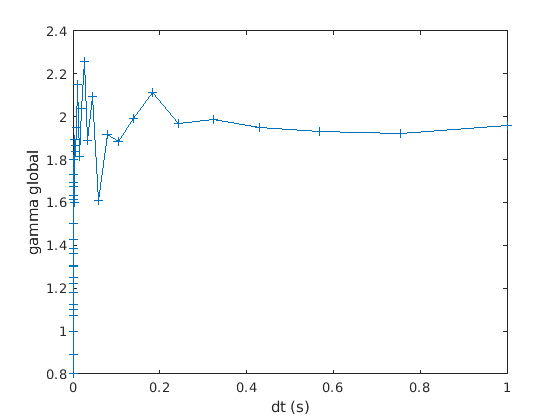

plot(dtTheo_test,gammaMean_dt,'-+')
xlabel('dt (s)')
ylabel('gamma global')

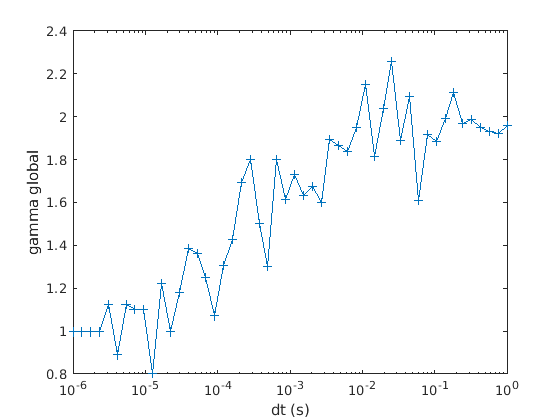


semilogx(dtTheo_test,gammaMean_dt,'-+')
xlabel('dt (s)')
ylabel('gamma global')

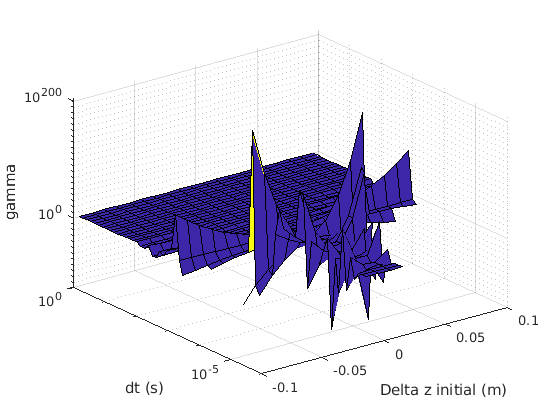


surf(initDistBin_,dtTheo_test, gamma_dt), h=gca;
set(h,'zscale','log');
% set(h,'xscale','log');
set(h,'yscale','log');
xlabel('Delta z initial (m)')
ylabel('dt (s)')
zlabel('gamma')

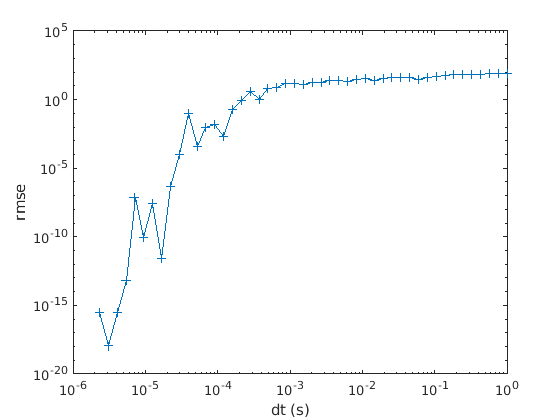

loglog(dtTheo_test,rmse_dt,'-+')
xlabel('dt (s)')
ylabel('rmse')

### En fonction de $K$

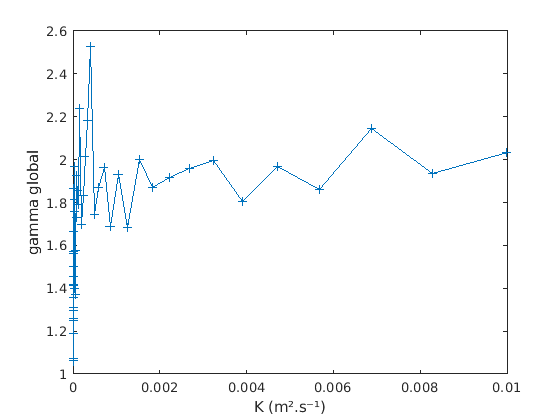

dzInit = 0.01;
initDistBin = -0.1:dzInit:0.1;
initDistBin_ = (initDistBin(1:end-1)+initDistBin(2:end))./2;

gammaK = nan(length(K_test),length(initDistBin_));
gammaKMean = nan(length(K_test),1);
rmseK = nan(length(K_test),1);
for iK = 1:length(K_test)
    DataColA = savedCollisions{iK,1};
    DataColB = savedCollisions{iK,2};
    fitA = fitdist(DataColA,'Normal');
    fitB = fitdist(DataColB,'Normal');
    gammaK(iK,:) = pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)./(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB));
    gammaKMean(iK) = numel(DataColA)/numel(DataColB);
    rmseK(iK,1) = sqrt(sum((pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)-(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB))).^2));
    
end

plot(K_test,gammaKMean,'-+')
xlabel('K (m².s⁻¹)')
ylabel('gamma global')

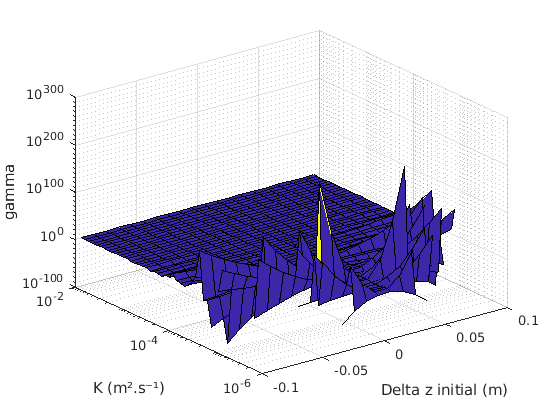


surf(initDistBin_,K_test, gammaK), h=gca;
set(h,'zscale','log');
% set(h,'xscale','log');
set(h,'yscale','log');
xlabel('Delta z initial (m)')
ylabel('K (m².s⁻¹)')
zlabel('gamma')

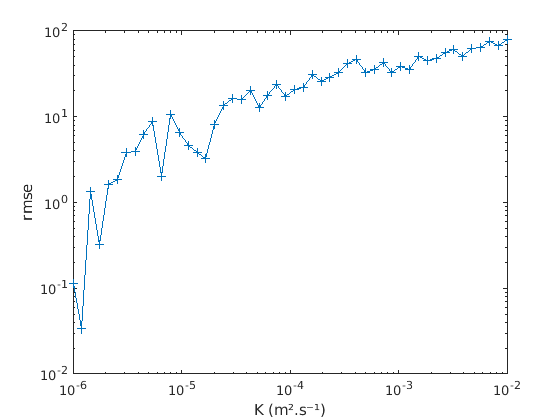


loglog(K_test,rmseK,'-+')
xlabel('K (m².s⁻¹)')
ylabel('rmse')

### En fonction de $dt K$

clear,
load('/media/ian/Transcend/MPsDistrib/Results/Aggr/dtK_collision_sort_data.mat')
load('/media/ian/Transcend/MPsDistrib/Results/Aggr/dtK_collision_data_sort2.mat')

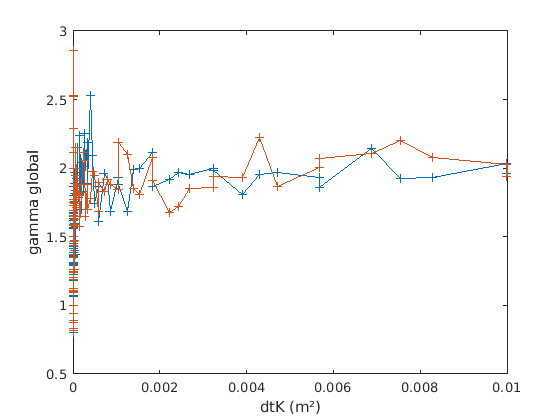

dzInit = 0.01;
initDistBin = -0.1:dzInit:0.1;
initDistBin_ = (initDistBin(1:end-1)+initDistBin(2:end))./2;

gamma = nan(length(dtK_sort),length(initDistBin_));
gammaMean = nan(length(dtK_sort),1);
rmse = nan(length(dtK_sort),1);
gamma2 = nan(length(dtK_sort),length(initDistBin_));
gammaMean2 = nan(length(dtK_sort),1);
rmse2 = nan(length(dtK_sort),1);
for i = 1:length(dtK_sort)
    DataColA = dtK_collisions_sort{i,1};
    DataColB = dtK_collisions_sort{i,2};
    fitA = fitdist(DataColA,'Normal');
    fitB = fitdist(DataColB,'Normal');
    gammaMean(i) = numel(DataColA)/numel(DataColB);
    rmse(i,1) = sqrt(sum((pdf(fitA,initDistBin_).*dzInit.*numel(DataColA)-(pdf(fitB,initDistBin_).*dzInit.*numel(DataColB))).^2));
    
    DataColA2 = dtK_collisions_sort2{i,1};
    DataColB2 = dtK_collisions_sort2{i,2};
    fitA2 = fitdist(DataColA2,'Normal');
    fitB2 = fitdist(DataColB2,'Normal');
    gammaMean2(i) = numel(DataColA2)/numel(DataColB2);
    rmse2(i,1) = sqrt(sum((pdf(fitA2,initDistBin_).*dzInit.*numel(DataColA2)-(pdf(fitB2,initDistBin_).*dzInit.*numel(DataColB2))).^2));
    
end


plot(dtK_sort,gammaMean,'-+', dtK_sort,gammaMean2,'-+')
xlabel('dtK (m²)')
ylabel('gamma global')

trh = 1e-6;
mean([gammaMean(dtK_sort >= trh);gammaMean2(dtK_sort >= trh)])

ans = 1.7622

xfit = [log(dtK_sort');log(dtK_sort')];
yfit = [gammaMean;gammaMean2];
X = [ones(length(xfit),1) xfit];
b = X\yfit

b =     2.5160
    0.0834


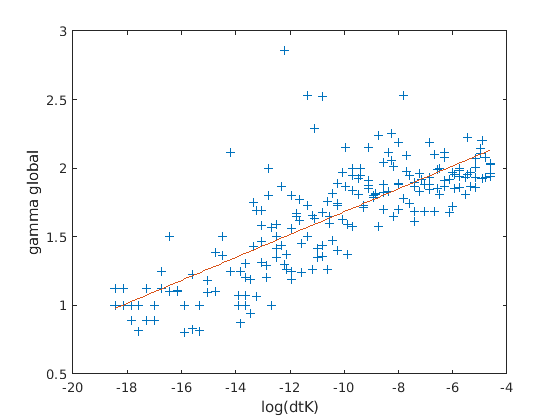


xplot = linspace(min(xfit),max(xfit),100);
yplot = xplot*b(2)+b(1);

plot(xfit,yfit,'+',xplot,yplot)
xlabel('log(dtK)')
ylabel('gamma global')

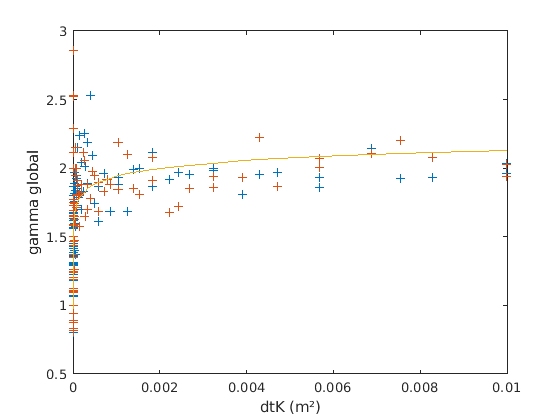

plot(dtK_sort,gammaMean,'+',dtK_sort,gammaMean2,'+', dtK_sort,b(2).*log(dtK_sort)+b(1),'-')
xlabel('dtK (m²)')
ylabel('gamma global')

$\gamma = \alpha ln(dt K) + \beta$ avec $\alpha = 0.0834$ et $\beta = 2.516$

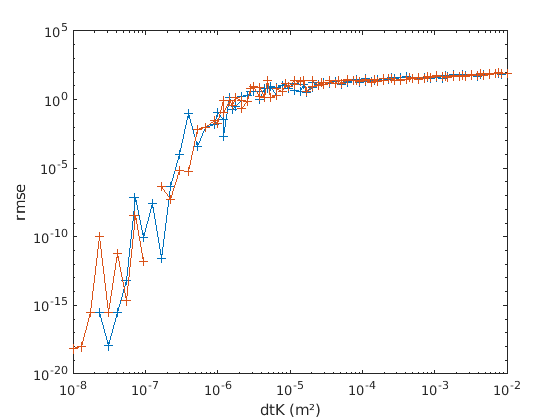

% plot(log(sqrt(dtK_sort)),log(gammaMean),'+')
% xlabel('sqrt(dtK) (m²)')
% ylabel('gamma global')
% 
% surf(initDistBin_,dtK_sort, gamma), h=gca;
% set(h,'zscale','log');
% % set(h,'xscale','log');
% set(h,'yscale','log');
% xlabel('Delta z initial (m)')
% ylabel('dtK (m²)')
% zlabel('gamma')
loglog(dtK_sort,rmse,'-+',dtK_sort,rmse2,'-+')
% loglog(1./dtK_sort,1./rmse,'-+')
xlabel('dtK (m²)')
ylabel('rmse')

## Étude de la variation des paramètres $\mu$ et $\sigma$ de la loi de col

## lision en fonction de $dt$ et $K$


$$\Delta z_{21}^{t+dt} \sim N\left( [u_2-u_1 + dK_2-dK_1]dt + \Delta z_{21}^t,\; \sqrt{2dt[\|\sigma_1\|K_1 + \|\sigma_2\|K_2]} \right)$$



$$\sigma = \sqrt{2dt[\|\sigma_1\|K_1 + \|\sigma_2\|K_2]}$$


Si on a $\sigma_1 = \sigma_2 = \sigma_R$ et $K = cst \Rightarrow K_1 = K_2 = K$


$$\sigma = \sqrt{4dt\|\sigma_R\|K}$$


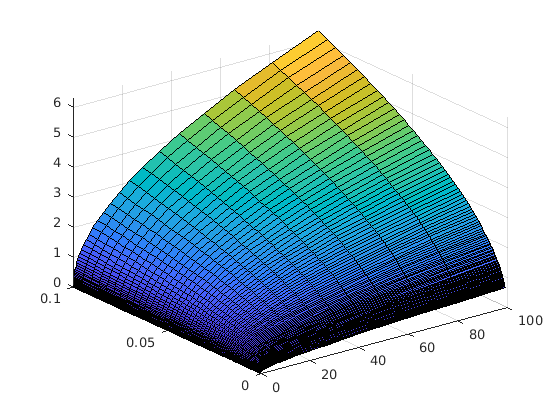

dt_x = logspace(-7,2,100);
K_y = logspace(-3,-1,100)';
sigR = 1;
sigma_z = sqrt(4*sigR.*K_y*dt_x);

surf(dt_x,K_y,sigma_z)

Si on fixe $\mu = 0$ (pas de déplacement) :

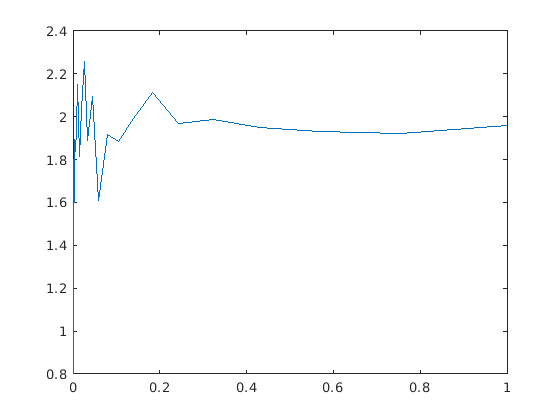

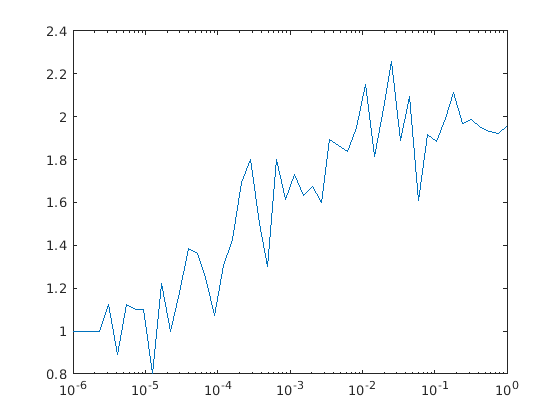

mu = 0;

DeltaZdt = cell(length(K_y),length(dt_x));
for idt = 1:length(dt_x)
    for iK = 1:length(K_y)
        DeltaZdt{iK,idt} = makedist('Normal','mu',mu,'sigma',sigma_z(iK,idt));
    end
end


xDist = -0.0005:1e-6:0.0005;
normDistPlot = nan(length(dt_x),length(xDist));
for idt = 1:length(dt_x)
    normDistPlot(idt,:) = pdf(DeltaZdt{50,idt},xDist);
%     plot(xDist,cdf(DeltaZdt{50,idt},xDist), 'DisplayName', num2str(dt_x(idt)))
%     hold on
end
% hold off
% legend('Location', 'bestoutside')
% lines = get(gca, 'Children');
% set(lines, {'Color'}, nToColorMap(length(lines)))
surf(dt_x, xDist, normDistPlot','LineStyle','none')
h=gca

h =   Axes with properties:

             XLim: [0 100]
             YLim: [-5.0000e-04 5.0000e-04]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


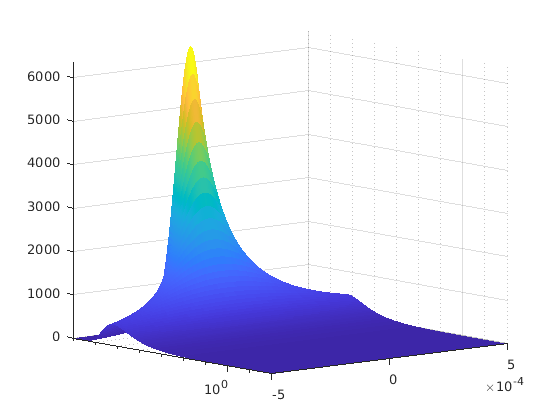

set(h,'xscale','log')